# Mess- und Regelungstechnik - Praktikum 4

Prof. Dr.-Ing. Anselm Haselhoff - Hochschule Ruhr West

## Aufgabe 1

Es wird wieder das Szenario des letzten Praktikums betrachtet.

### 1)

Messen Sie mit der gegebenen Funktion `measure` für Distanzen von 10m bis 70m in einem Abstand von 10m jeweils 100 Messwerte.

*Hinweis: Sie können der Funktion einen Vektor an Abständen übergeben. Dann werden mehrere Messungen hintereinander durchgeführt, und die Messwerte in einer Matrix zurückgegeben. Mit einem dritten, optionalen Parameter *`false`* kann die Visualisierung deaktiviert werden.*

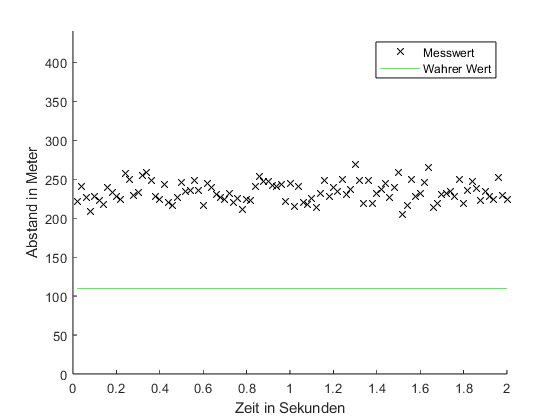

dist = 50:10:110; %horizontal vektor
samples = measure(100, dist, false);

### 2)

Berechnen Sie für jede Distanz (Spalten in der Matrix) den Mittelwert aus den Messwerten. Plotten Sie diese Werte mit einem x-Marker.

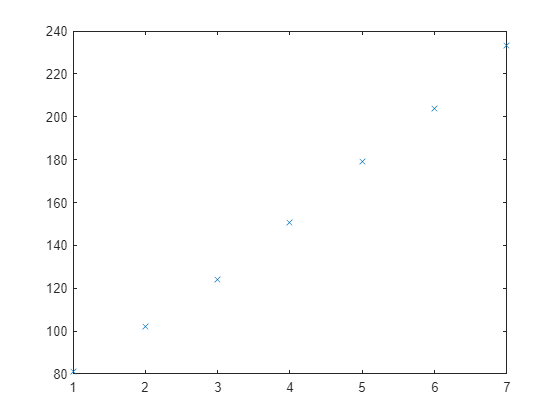

means = mean(samples);
plot(means, 'x');
hold on;

### 3)

Führen Sie eine Polynomapproximation durch, indem Sie die Koeffizienten für ein Polynom 3. Grades erstellen, das sich den Messwerten am besten anpasst. Nutzen Sie hierzu `polyfit`.

koeff = polyfit(1:1:7, means, 3);

### 4)

Erstellen Sie nun die zugehörigen Werte mit `polyval` und plotten Sie diese Werte zusammen mit den in **2)** angezeigten Mittelwerten.

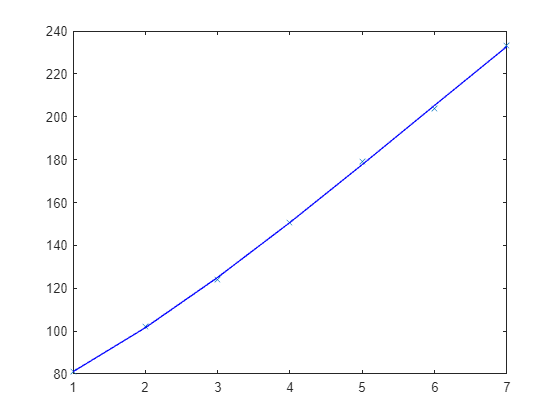

func = polyval(koeff, 1:1:7);
plot(func, 'blue');

### 5)

Führen Sie die letzten beiden Schritte für vertauschte Ein- und Ausgangswerte durch. Verwenden Sie hier die Farbe Rot.

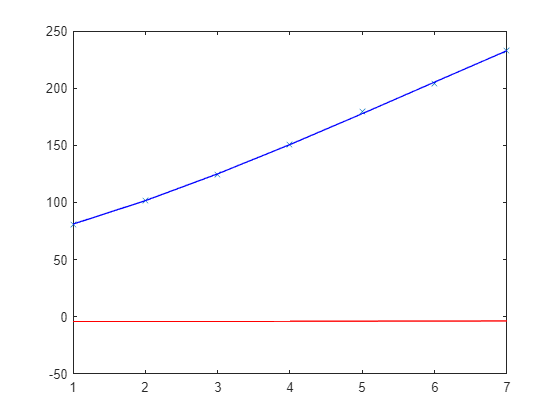

koeffInvert = polyfit(means, 1:1:7, 3);
funcInvert = polyval(koeffInvert, 1:1:7);

plot(funcInvert, 'red');

### 6)

Nutzen Sie nun `polyval` mit den Koeffizienten aus **5)** und den gemessenen Mittelwerten, um die korrigierten Mittelwerte zu erhalten. Plotten Sie diese Werte in grün.

z = polyval(koeffInvert, means);
disp(z);

    1.0045    2.0060    2.9673    4.0095    5.0590    5.9364    7.0173



disp(func);

   81.0736  101.6036  125.0710  150.7007  177.7176  205.3464  232.8122



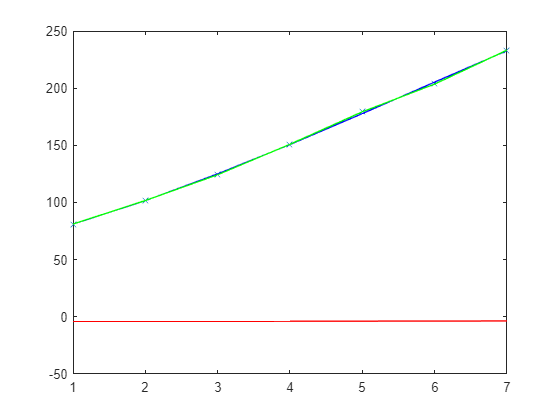

y = polyval(koeff, z);
plot(y, 'green');

### `7)`

Beschriften Sie alle Achsen, betiteln Sie die Grafik und legen Sie eine Legende an.

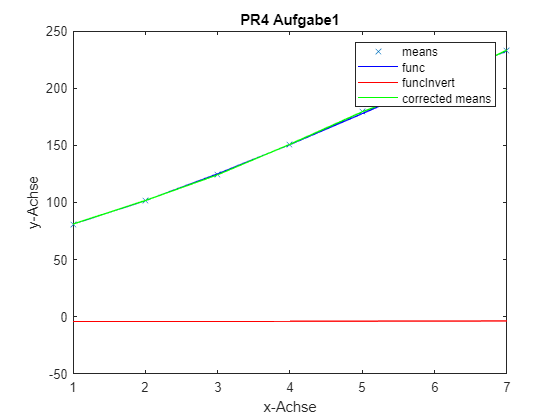

% Create title
title("PR4 Aufgabe1");

% Create ylabel
ylabel({'y-Achse'});

% Create xlabel
xlabel({'x-Achse'});

% Create legend
legend("means", "func", "funcInvert", "corrected means");
hold off;

## Aufgabe 2

Ein Fahrzeug startet an der Position $s_0$ und bewegt sich mit konstanter Geschwindigkeit $v_0$. Diese gleichförmige Bewegung lässt sich durch $y(t) = v_0 \cdot t + x_0$ beschreiben, wobei $y(t)$ die Position des Autos zum Zeitpunkt $t$ angibt.

Für $n$ Wertepaare $\{(t_1, y_1), (t_2, y_2), \dots , (t_n, y_n)\}$ kann zu dieser Gleichung das zugehörige lineare Gleichungssystem als Matrix-Vektor-Produkt dargestellt werden:


$$\begin{array}{c}
y & = & A & \cdot & x \\ \\
\left\lbrack \matrix{
y_1 \cr
y_2 \cr
\vdots \cr
y_n \cr
}\right\rbrack
& = &
\left\lbrack \matrix{
(t_1)^1 & (t_1)^0 \cr
(t_2)^1 & (t_2)^0 \cr
\vdots & \vdots \cr
(t_n)^1 & (t_n)^0 \cr
}\right\rbrack
& \cdot &
\left\lbrack \matrix{
v_0 \cr
s_0 \cr
}\right\rbrack
\end{array}$$


Es existiert ein idealer Sensor, mit dem die Position $y(t)$ exakt gemessen werden kann. Mit diesem Sensor werden zu bestimmten Zeitpunkten Messungen aufgenommen:

values = [4 20; 4 20];
t = values(:, 1)

t =      4
     4


y = values(:, 2)

y =     20
    20


A = [ t ones(length(values), 1) ]

A =      4     1
     4     1


### 1)

Plotten Sie die Werte in einer Grafik mit x-Markern. Wählen Sie in der Choicebox andere Wertepaare aus. Überlegen Sie, wie Sie die Punkte im Plot mit einer Gerade interpolieren bzw. approximieren können.

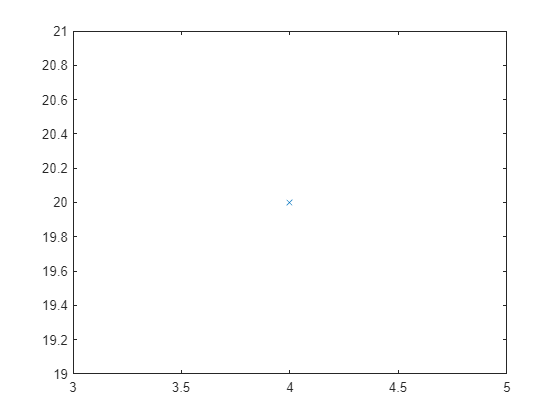

length = 2;
plot(values(1:length, 1), values(1:length, 2), 'x');
hold on;

% Interpolation mittels polyfit-Funktion in MatLab
% Interpolation mittels eines LGS für zwei Punkte
koeffLin = polyfit(values(1:length, 1), values(1:length, 2), 1)

koeffLin =     5.0000         0


### 2)

Berechnen Sie $x$ aus den gemessenen Werten, verwenden Sie zunächst `inv` zum invertieren der Matrix. Warum ist das invertieren mit `inv` nicht bei allen Wertepaaren möglich?

% Bildung eines Inversen nur möglich, wenn quadratische Matrix (gleich viele Zeilen
% wie Spalten), sprich Determinate != 0
% Das dritte und vierte Wertepaar sind keine quadratischen Matrizen,
% demnach kann das Inverse nicht gebildet werden.
invertA = inv(A);

x1 = invertA * y;
disp(x1);

   Inf
   Inf



### 3)

Verwenden sie nun `pinv` oder den `\`-Operator. Unter welchen Umständen können diese ein Ergebnis liefern? Welche Besonderheiten weisen die Wertepaare bzgl. der Lösbarkeit des Gleichungssystems auf? Welche Konsequenzen hat dies für die Berechenbarkeit bzw. Bestimmtheit von $x$?

Recherchieren Sie, wie sie mithilfe des Rangs (`rank`) und der Determinante (`det`) einer Matrix die Lösbarkeit beurteilen können.

% ...
pinvertA = pinv(A);
x2 = pinvertA * y;
disp(x2);

    4.7059
    1.1765




x3 = A \ y;

disp(x3);

   NaN
   NaN



### 4)

Plotten Sie in die Grafik aus **1)** zusätzlich den Verlauf der Funktion $y(t)$ für den in **2)** berechneten Vektor $x$ im Bereich $t \in \left[ 0; 10 \right]$.

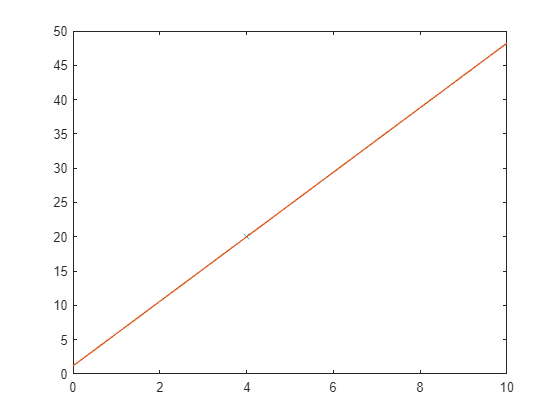

t = 0:10;
y = x2(1,1) * t + x2(2,1);
plot(t, y);
hold off;

Es wird nun eine gleichmäßig beschleunigte Bewegung - eine Verallgemeinerung der gleichförmigen Bewegung - betrachtet:


$$y(t) = \frac{1}{2}a_0 \cdot t^2 + v_0 \cdot t + x_0$$


Das zugehörige Gleichungssystem für $n$ Wertepaare entspricht dann:


$$\begin{array}{c}
y & = & A & \cdot & x \\
\\
\left\lbrack \matrix{
y_1 \cr
y_2 \cr
\vdots \cr
y_n \cr
}\right\rbrack
& = &
\left\lbrack \matrix{
(t_1)^2 & (t_1)^1 & (t_1)^0 \cr
(t_2)^2 & (t_2)^1 & (t_2)^0 \cr
\vdots & \vdots \cr
(t_n)^2 & (t_n)^1 & (t_n)^0 \cr
}\right\rbrack
& \cdot &
\left\lbrack \matrix{
a_0 \cr
v_0 \cr
s_0 \cr
}\right\rbrack
\end{array}$$


Es stehen wieder ähnliche Wertepaare zur Verfügung:

values_a = [0 0; 4 20; 5 25];
t_a = values_a(:,1);
y_a = values_a(:,2);

Anstatt die Matrix wie zuvor aus den Spalten zusammenzusetzten, kann sie für den allgemeinen Fall (für Koeffizienten steigender Grade $t^3, t^4, \dots$) aus den letzten 3 Spalten einer Vandermonde-Matrix extrahiert werden:

A_a = vander(t_a);
A_a = A_a(:, end-3+1:end)

A_a =      0     0     1
    16     4     1
    25     5     1


### 5)

Plotten Sie auch diese Werte in eine neue Grafik mit x-Markern.

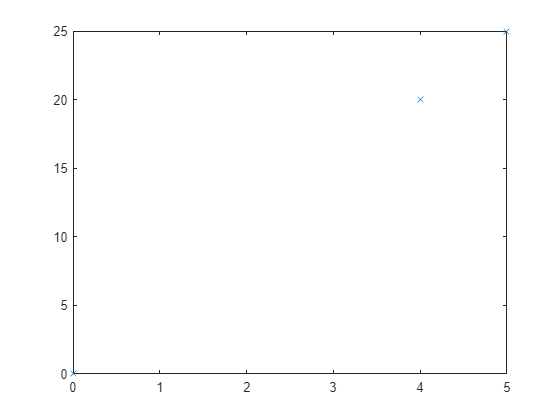

length_a = 3;
plot(values_a(1:length_a, 1), values_a(1:length_a, 2), 'x');

### 6)

Berechnen Sie wieder den Vektor $x$.

*Tipp: Benennen Sie die Variable *`x_a`*, um sie nicht mit den Variablen aus dem ersten Aufgabenteil zu vertauschen.*

x_a = A_a \ y_a;
disp(x_a);

   -0.0000
    5.0000
         0



### 7)

Wie und warum unterscheiden sich das Ergebnisse insbesondere für die Wertepaare, die bereits bei der gleichförmigen Bewegung zur Auswahl standen?

% Dadurch dass mehr Wertepaare betrachtet werden, wirkt sich auch die
% Invertierung anders aus (?)

### 8)

Plotten Sie in die Grafik aus **5)** zusätzlich den Verlauf der Funktion $y(t)$ für den in **6)** berechneten Vektor $x$ im Bereich $t \in \left[ 0; 10 \right]$.

*Tipp: Wenn Sie den Plot in ****4)**** geschickt umgesetzt haben, brauchen Sie nur den Variablennamen von *$x$ *zu ändern.*

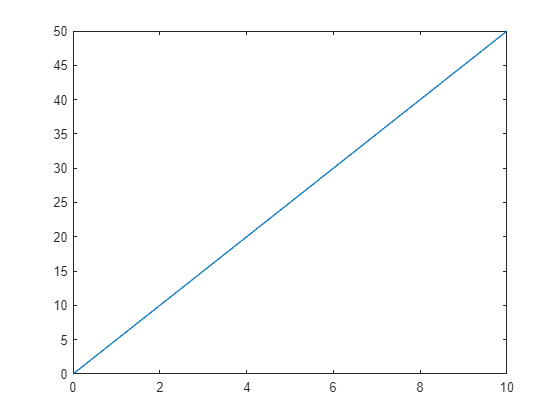

y_a_t = 0.5 * x_a(1,1) * (t.*t) + x_a(2,1) * t + x_a(3,1);
plot(t, y_a_t); % warum linear?